syms Vo t R C phi omega a omega1 omega2 t0 m
f=Vo*(1-exp(-t/(R*C)))*heaviside(t)

$$f = -\mathrm{Vo}\,\mathrm{heaviside}\left(t\right)\,\left({\mathrm{e}}^{-\frac{t}{C\,R}}-1\right)$$

laplace(f)

$$ans = \mathrm{Vo}\,\left(\frac{1}{s}-\frac{1}{s+\frac{1}{C\,R}}\right)$$


f=Vo*exp(-a*t)*sin(omega*t+phi)*heaviside(t)

$$f = \mathrm{Vo}\,{\mathrm{e}}^{-a\,t}\,\sin\left(\phi +\omega \,t\right)\,\mathrm{heaviside}\left(t\right)$$

laplace(f)

$$ans = \mathrm{Vo}\,\left(\frac{\sin\left(\phi \right)\,\left(a+s\right)}{{\left(a+s\right)}^{2}+\omega^{2}}+\frac{\omega \,\cos\left(\phi \right)}{{\left(a+s\right)}^{2}+\omega^{2}}\right)$$


f=heaviside(t)*(1-(omega2/(omega2-omega1)*exp(-omega2*t))-(omega1/(omega1-omega2)*exp(-omega2*t)))

$$f = \mathrm{heaviside}\left(t\right)\,\left(\frac{\omega_{2}\,{\mathrm{e}}^{-\omega_{2}\,t}}{\omega_{1}-\omega_{2}}-\frac{\omega_{1}\,{\mathrm{e}}^{-\omega_{2}\,t}}{\omega_{1}-\omega_{2}}+1\right)$$


laplace(f)

$$ans = \frac{1}{s}-\frac{1}{\omega_{2}+s}$$

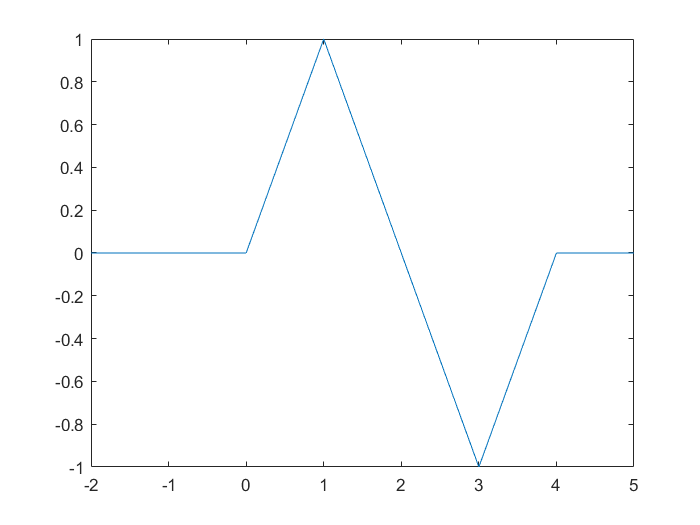


syms t
fplot(t*heaviside(t)-2*(t-1)*heaviside(t-1)+2*(t-3)*heaviside(t-3)-(t-4)*heaviside(t-4), [-2, 5])

f=t*heaviside(t)-2*(t-1)*heaviside(t-1)+2*(t-3)*heaviside(t-3)-(t-4)*heaviside(t-4)

$$f = t\,\mathrm{heaviside}\left(t\right)-\mathrm{heaviside}\left(t-4\right)\,\left(t-4\right)-\mathrm{heaviside}\left(t-1\right)\,\left(2\,t-2\right)+\mathrm{heaviside}\left(t-3\right)\,\left(2\,t-6\right)$$

laplace(f)

$$ans = \frac{2\,{\mathrm{e}}^{-3\,s}}{s^{2}}-\frac{2\,{\mathrm{e}}^{-s}}{s^{2}}-\frac{{\mathrm{e}}^{-4\,s}}{s^{2}}+\frac{1}{s^{2}}$$

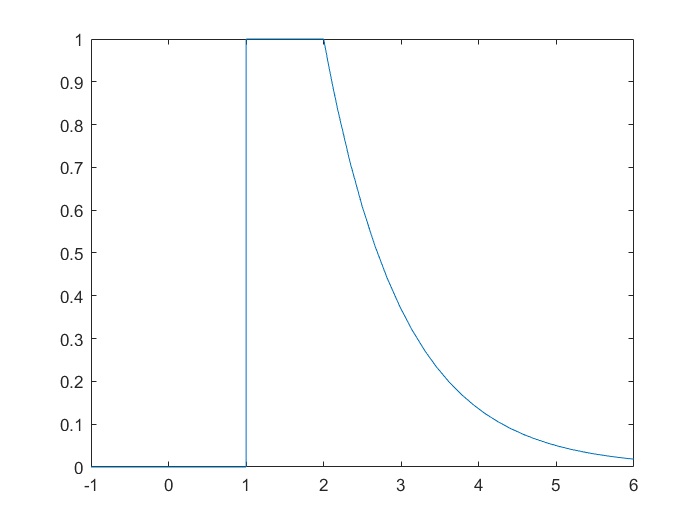


fplot(heaviside(t-1)-(1-exp(-(t-2)))*heaviside(t-2),[-1 6])

f=heaviside(t-1)-(1-exp(-(t-2)))*heaviside(t-2)

$$f = \mathrm{heaviside}\left(t-1\right)+\mathrm{heaviside}\left(t-2\right)\,\left({\mathrm{e}}^{2-t}-1\right)$$

laplace(f)

$$ans = {\mathrm{e}}^{-2\,s}\,\left(\frac{1}{s+1}-\frac{1}{s}\right)+\frac{{\mathrm{e}}^{-s}}{s}$$


f=sin(2*omega*(t-t0))

$$f = \sin\left(2\,\omega \,\left(t-t_{0}\right)\right)$$

laplace(f)

$$ans = \frac{2\,\omega \,\cos\left(2\,\omega \,t_{0}\right)-s\,\sin\left(2\,\omega \,t_{0}\right)}{4\,\omega^{2}+s^{2}}$$


f = t^2*exp(-m*t)

$$f = t^{2}\,{\mathrm{e}}^{-m\,t}$$

laplace(f)

$$ans = \frac{2}{{\left(m+s\right)}^{3}}$$

assume(t0,'real')
f= sin(2*omega*(t-t0))*heaviside(t-2*t0)

$$f = \mathrm{heaviside}\left(t-2\,t_{0}\right)\,\sin\left(2\,\omega \,\left(t-t_{0}\right)\right)$$

laplace(f)

$$ans = \begin{array}{l} -\cos\left(2\,\omega \,t_{0}\right)\,\left(\frac{\sigma_{1}\,\mathrm{i}}{2}-\frac{\sigma_{2}\,\mathrm{i}}{2}\right)-\sin\left(2\,\omega \,t_{0}\right)\,\left(\frac{\sigma_{1}}{2}+\frac{\sigma_{2}}{2}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{laplace}\left(\mathrm{heaviside}\left(t-2\,t_{0}\right),t,s-2\,\omega \,\mathrm{i}\right)\\ \sigma_{2}=\mathrm{laplace}\left(\mathrm{heaviside}\left(t-2\,t_{0}\right),t,s+2\,\omega \,\mathrm{i}\right) \end{array}$$